df_raw = load("\\wsl.localhost\Ubuntu\home\merlijn\projects\brain_computer_project\ass1\artefacts.mat")

df_raw = struct with fields:
    art: [120×23501 single]



df = df_raw.art

df = 120×23501 single matrix
    3.4503   -7.0766   -5.6607   -3.1376   -0.3729    1.2657   -2.8201    2.3525   15.6208   24.7359   16.2792   -1.1520    6.6818   15.2077    4.9019    0.0572   -9.7865  -28.8859  -26.7107  -12.9802   -6.4609   -4.8388  -15.3036  -20.1829  -18.9540  -15.1957    5.1017   10.0343   -9.1356    6.2597   28.4815    5.7002   -8.6162  -14.4915  -22.8277  -13.9759  -10.1751  -11.2743   -7.2434   -8.1461  -17.0400  -25.2681  -29.0224  -26.6746  -27.7695  -45.1659  -43.7548  -13.5530   -2.9182   -4.8241
   -2.5810   -8.2664   -3.1903    4.4202    8.2348    3.3193   -5.6564    1.2940   11.6009   14.9069    9.4474   -4.8010    0.6692    8.7986   -0.4968   -5.7796   -2.3369    0.0606   -0.9945   -5.8263  -10.8764  -14.0471  -19.6323  -17.1482  -19.6076  -21.6544   -1.8915    3.0724  -17.0047   -6.8915   17.5220    2.6776  -10.8604   -9.0119  -11.9693  -14.5467  -19.1217  -15.5831  -11.1102  -15.9731  -21.4800  -19.2663  -16.1781  -24.0086  -22.4480  -17.0830  -20.4335


Fz = df(12, :)

Fz = 1×23501 single row vector
    0.3788   -7.6028   -3.9853    5.5309    7.6808    2.6613    1.4865   14.6628   23.2530   21.4154   15.9946    6.1915    7.7843   10.9985    3.5304   -1.3009    2.1662    4.4547    1.0567   -2.0391   -3.8636  -10.7283  -19.3910  -17.4801  -22.1026  -26.1141   -5.9473    1.1159  -20.2632   -9.2282   20.1586    3.1839  -17.8050  -17.5626  -15.7205  -14.5825  -20.8600  -20.6945  -14.0499  -15.9080  -21.3106  -18.3213  -13.9049  -19.8729  -15.5170  -10.0918  -15.4842  -13.0683  -19.8569  -25.6015


Cz = df(22, :)

Cz = 1×23501 single row vector
   -6.5379  -17.2776  -14.5965   -4.1611    1.9782   -1.6096   -3.1711   14.7091   28.9567   29.4827   25.7802   17.2761   18.8557   20.7650   13.3772    8.8094   10.6247   12.8668   11.3035    8.8128    3.6591  -10.1952  -24.2774  -26.6182  -34.8612  -39.1629  -19.7518  -16.0455  -42.0081  -34.3347   -5.1503  -21.1683  -37.8120  -32.3171  -26.8492  -18.6451  -16.6901  -11.7836   -4.8484   -6.1826   -7.7907   -3.5384   -0.7073   -5.7936   -1.3038    2.9663   -2.7878   -2.4335  -11.1444  -19.8147


Oz = df(42, :)

Oz = 1×23501 single row vector
   11.4585    9.4993   12.7124    8.2832    2.4808   -1.1940   -0.6064    8.6617   18.0331   15.5271    3.5486    0.9981    5.2505    2.1176   -5.3338   -7.4697    1.5579    5.3830    1.8114    1.4082    3.4288   -3.6855  -16.3197  -12.7737  -15.3709  -21.4381   -2.4844    2.9157  -24.3687  -16.0151   23.5250   16.3123   -2.0357   -1.4577   -2.3575    1.6766   -1.1173   -5.5648    4.6102    7.3302   -1.3539    4.6370    9.1828    5.3452    2.9766   -6.7732   -6.0790    3.1119    1.1912    0.8410



FzNeighbours_idx = [7, 13, 17, 11] %Afz, F2, FCz, F1

FzNeighbours_idx =      7    13    17    11


CzNeighbours_idx = [17, 23, 27, 21] %FCz, C2, CPz, C1

CzNeighbours_idx =     17    23    27    21


OzNeighbours_idx = [37, 43, 47, 41] %POz, O2, iz, O1

OzNeighbours_idx =     37    43    47    41




function neighbours = getNeighbours(df, neighbour_idx)
    neighbours = df(neighbour_idx, :);
end

FzNeighbours = getNeighbours(df, FzNeighbours_idx);
CzNeighbours = getNeighbours(df, CzNeighbours_idx);
OzNeighbours = getNeighbours(df, OzNeighbours_idx);


Fz_lap = Fz - mean(FzNeighbours, 1);
Cz_lap = Cz - mean(CzNeighbours, 1);
Oz_lap = Oz - mean(OzNeighbours, 1);

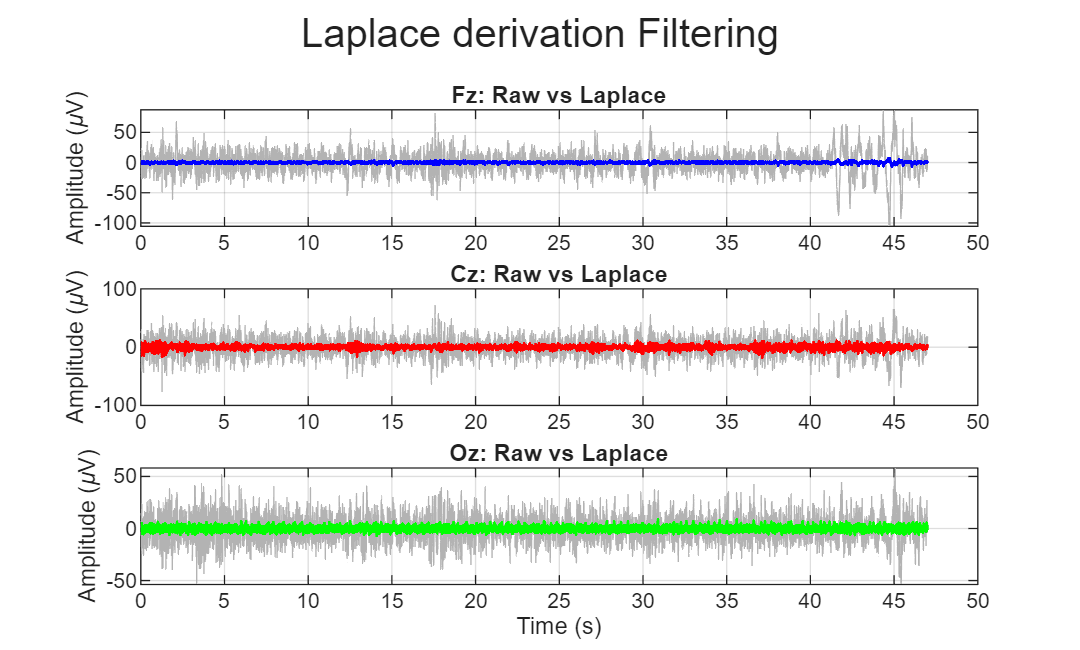

% sampling rate
fs = 500;
% Create a time vector in seconds. Since sampling interval T = 1/fs, we need vector
% with intervals of 0.002 sec
t = (0:size(df, 2) - 1) / fs;

%% Plotting - base in grey, other in rgb
figure;
sgtitle('Laplace derivation Filtering');

% Plot Fz
subplot(3, 1, 1);
plot(t, Fz, 'Color', [0.7 0.7 0.7]); 
hold on;
plot(t, Fz_lap, 'b', 'LineWidth', 1);
title('Fz: Raw vs Laplace');
ylabel('Amplitude (\muV)');
grid on;

% Plot Cz
subplot(3, 1, 2);
plot(t, Cz, 'Color', [0.7 0.7 0.7]); 
hold on;
plot(t, Cz_lap, 'r', 'LineWidth', 1);
title('Cz: Raw vs Laplace');
ylabel('Amplitude (\muV)');
grid on;

% Plot Oz
subplot(3, 1, 3);
plot(t, Oz, 'Color', [0.7 0.7 0.7]); 
hold on;
plot(t, Oz_lap, 'g', 'LineWidth', 1);
title('Oz: Raw vs Laplace');
xlabel('Time (s)');
ylabel('Amplitude (\muV)');
grid on;